# **BEYİN FIRTINASI - 4**

### 1) n. Dereceden Türev

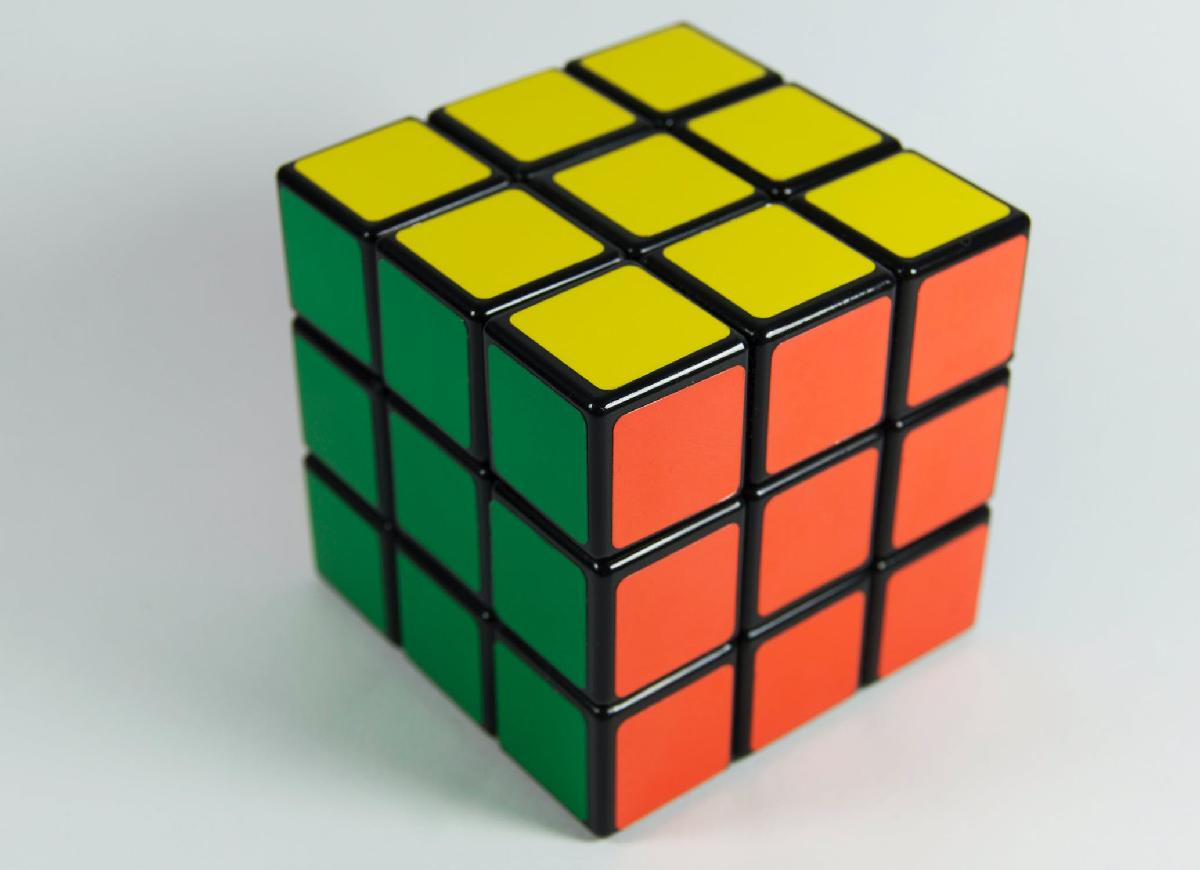

İlk problem olarak n. dereceden türev alan bir fonksiyon yazacağız. Fonksiyonun girdileri bir $f$ matematiksel fonksiyonu, bu matematiksel fonksiyonun tanımlandığı bir $x$ aralığı ve türev derecesidir. Yazacağımız fonksiyon, $f$ ve $x$ girdilerini kullanarak $\frac{d^{n}(f)}{dx^{n}}$ n. dereceden türevi hesapladıktan sonra bu türevi ve bu türevin tanımlandığı yeni $x$ aralığını çıktıya verecektir. Fonksiyonu oluşturduktan sonra sinüsün ilk 4 mertebeden türevlerinin aşağıdaki gibi olduğunu teyit edeceğiz:

- 
$$\frac{d(\sin(x))}{dx} = \cos(x)$$


- 
$$\frac{d^2(\sin(x))}{dx^2} = -\sin(x)$$


- 
$$\frac{d^3(\sin(x))}{dx^3} = -\cos(x)$$


- 
$$\frac{d^4(\sin(x))}{dx^4} = \sin(x)$$


Aşağıdaki kodlarda "Fonksiyon" yerine kendi yazdığınız fonksiyonun ismini yazınız. Sonrasında kodu çalıştırarak elde ettiğiniz figürde fonksiyonunuz sonucu oluşan değerlerin olması gereken değerlerle üst üste çıktığını teyit ediniz. Elde etmeyi beklediğimiz figür aşağıdaki gibidir:

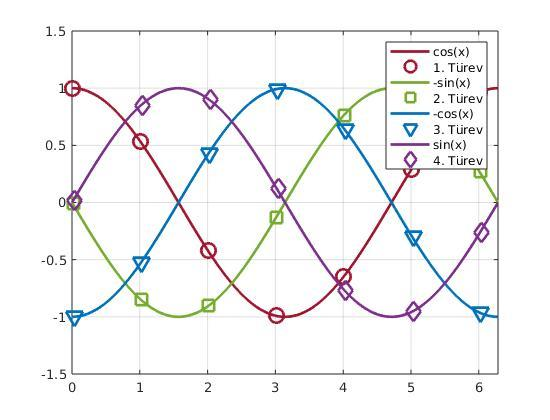

x = 0 : 0.01 : 2 * pi;
f = sin(x);
[fd1, xd1] = Fonksiyon(f, x, 1);
[fd2, xd2] = Fonksiyon(f, x, 2);
[fd3, xd3] = Fonksiyon(f, x, 3);
[fd4, xd4] = Fonksiyon(f, x, 4);
plot(x, cos(x), "-", "Color", [0.6350 0.0780 0.1840],...
                     "LineWidth", 2);
hold on;
plot(xd1(1 : 100 : 601), fd1(1 : 100 : 601),...
                    "o", "Color", [0.6350 0.0780 0.1840],...
                    "LineWidth", 2,...
                    "MarkerSize", 11);
hold on;
plot(x, -sin(x), "-", "Color", [0.4660 0.6740 0.1880],...
                     "LineWidth", 2);
hold on;
plot(xd2(1 : 100 : 601), fd2(1 : 100 : 601),...
                    "s", "Color", [0.4660 0.6740 0.1880],...
                    "LineWidth", 2,...
                    "MarkerSize", 11);
hold on;
plot(x, -cos(x), "-", "Color", [0 0.4470 0.7410],...
                     "LineWidth", 2);
hold on;
plot(xd3(1 : 100 : 601), fd3(1 : 100 : 601),...
                    "v", "Color", [0 0.4470 0.7410],...
                    "LineWidth", 2,...
                    "MarkerSize", 11);
hold on;
plot(x, sin(x), "-", "Color", [0.4940 0.1840 0.5560],...
                     "LineWidth", 2);
hold on;
plot(xd4(1 : 100 : 601), fd4(1 : 100 : 601),...
                    "d", "Color", [0.4940 0.1840 0.5560],...
                    "LineWidth", 2,...
                    "MarkerSize", 11);
legend("cos(x)", "1. Türev",...
       "-sin(x)", "2. Türev",...
       "-cos(x)", "3. Türev",...
       "sin(x)", "4. Türev");
xlim([0 2 * pi])
ylim([-1.5 1.5])
grid;

### 2) Ondalıktan İkiliğe

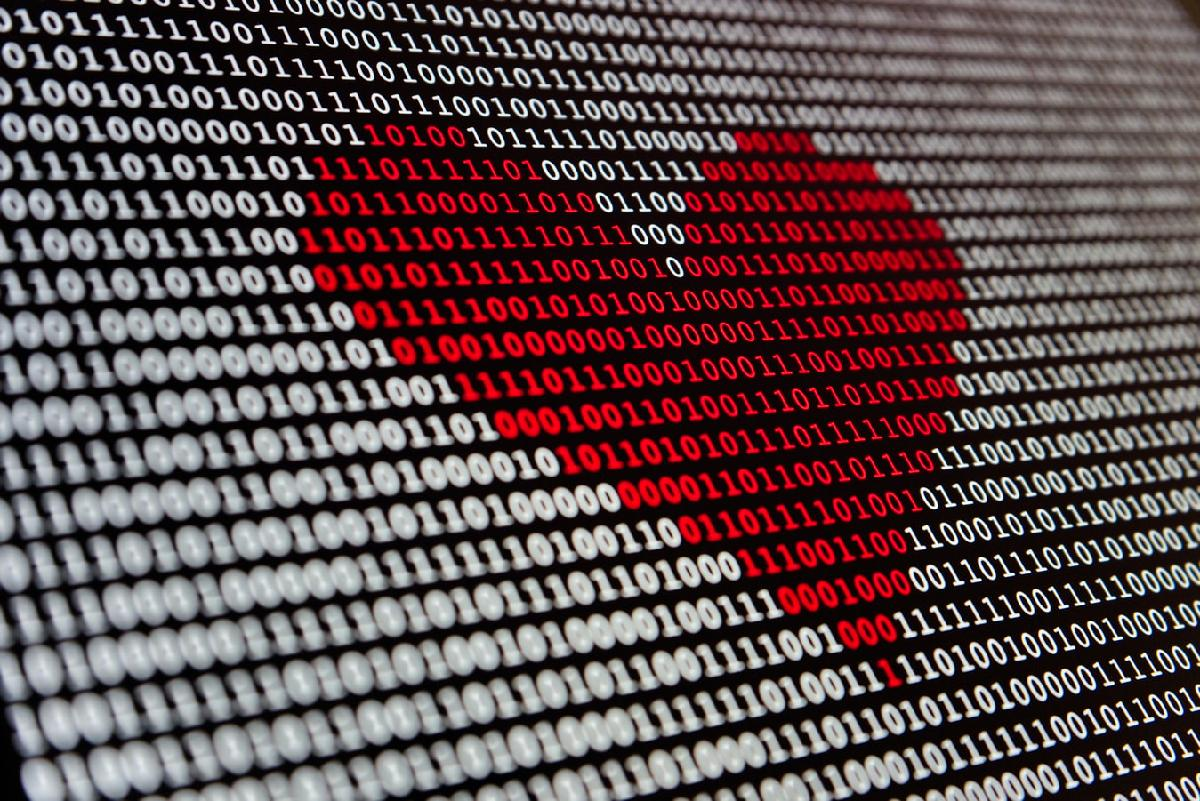

İkinci problemde zorluğu biraz daha arttırıyoruz. Ondalık sayıyı bitlere çeviren bir fonksiyon oluşturacağız. Fonksiyonun girdileri bir ondalık sayı ve kaç bite çevireceğimiz bilgisidir. Yazacağımız fonksiyon, girdi olarak aldığı ondalık sayıyı, yine girdi olarak aldığı bit sayısındaki bit vektörüne çevirdikten sonra elde ettiği vektörü çıktı olarak verecektir. Ancak burada kontrol etmek istediğimiz bir husus var. Biliyorsunuz her ondalık sayı her sayıdaki bite çevrilemez. Mesela 4 sayısını 1 bit ile gösteremezsiniz, en az 2 bite ihtiyacınız var. Bu kontrolü yapabilmek için fonksiyon, eğer girdi olarak aldığı ondalık sayı değeri yine girdi olarak aldığı bit sayısı ile gösterilemiyorsa hata verecektir. MATLAB'de ***error*** olarak tanımlanmış bir hazır fonksiyon bulunmaktadır. Bu fonksiyonun nasıl çalıştığını internetten araştırabilirsiniz veya ilk derste öğrendiğimiz gibi ***help*** komutunu kullanarak öğrenebilirsiniz. Yapmanız gereken şey, hata verilecek durumda ***error*** fonksiyonu ile aşağıdaki hata mesajını göstermektir:

"d can't be represented with n bits!"

Yukarıdaki hata mesajında "d" ve "n" yerine fonksiyona girdi olarak alınan ondalık sayı ve bit sayısı değerleri yazılmalıdır. Eğer hata durumu yoksa ondalık sayı bitlere çevrilip çıktıya verilecektir. Fonksiyonu yazdıktan sonra aşağıdaki kodlarda "Fonksiyon" yazan yere kendi yazdığınız fonksiyonun ismini yazınız ve ilk satırı çalıştırarak aşağıda verilen hata mesajını aldığınızdan emin olunuz:

"9 can't be represented with 3 bits!"

Sonrasında 9 sayısını 4 bit ile ifade eden fonksiyonu çalıştırıp son satırda beklenen sonucun alınıp alınmadığını kontrol ediniz.

Fonksiyon(9, 3);

bits = Fonksiyon(9, 4);
bits_check = mean(bits == [1 0 0 1]); % bits_check is expected to be 1

### 3) Ayın Kaçı?

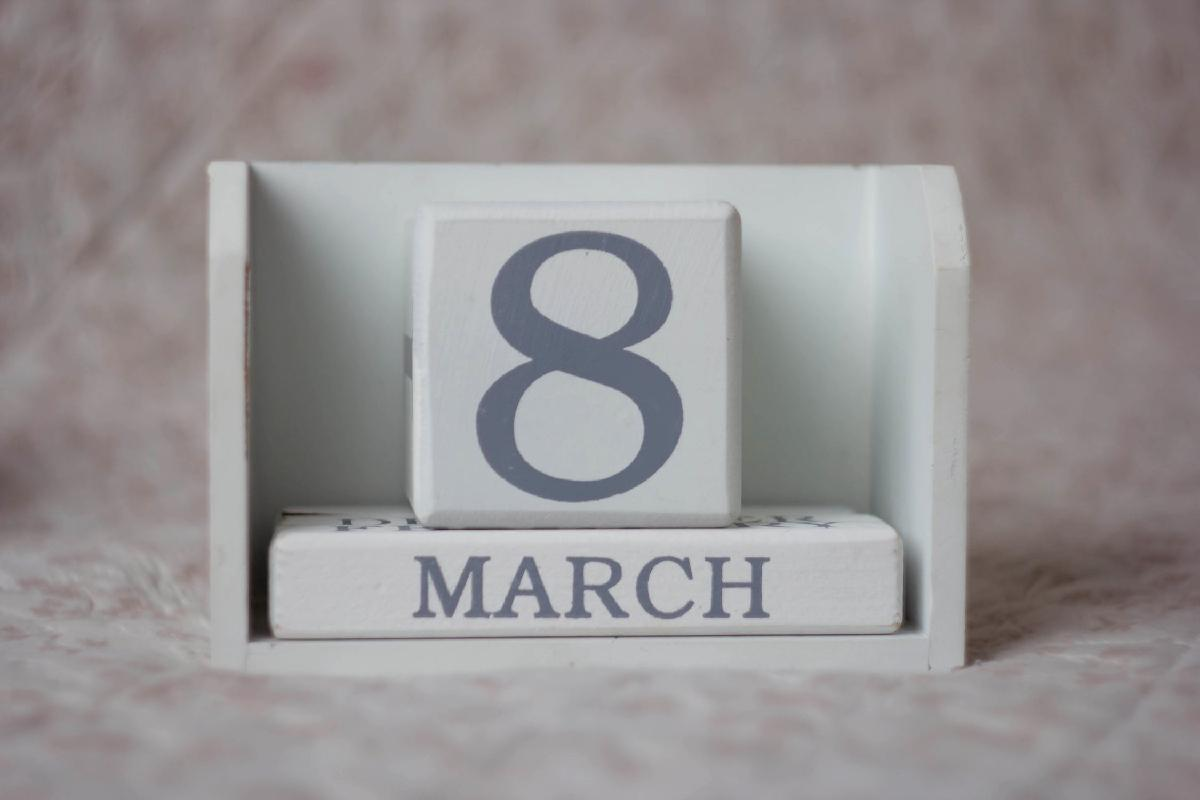

Üçüncü ve son problemimizde çıtayı biraz daha yukarı koyuyoruz. Verilen bir tarihe, belirli sayıda gün ekleyince yeni tarih ne olur bulmaya çalışacağız. Bu fonksiyonumuzda ilk girdi olarak gün, ay ve yıldan oluşan bir vektör alacağız. Fonksiyonun ilk girdisi aşağıdaki gibi bir vektör olmalıdır:


$$\matrix{
[\text{Gün} & \text{Ay} & \text{Yil}]
}$$


Örnek verecek olursak 17 Mayıs 2000 tarihi aşağıdaki gibi vektöre çevirilmelidir:


$$\matrix{
[\text{17} & \text{5} & \text{2000}]
}$$


İkinci girdi olarak da bu tarihe eklenecek olan gün sayısı girilecektir. Şubat ayının 28 gün ve diğer ayların 30 veya 31 gün (aya göre karar verilecektir) olduğu bilgisinden yola çıkarak, aldığı girdilere göre yeni gün, ay ve yıldan oluşan vektörü girdideki vektör ile aynı formatta elde edip çıktıya veren fonksiyonu yazınız. Sonrasında da yazdığınız fonksiyonu kontrol etmek adına, aşağıdaki kodda "Fonksiyon" yazan yere kendi yazdığınız fonksiyonun ismini yazarak, 17 Mayıs 2000 tarihinden 4953 gün sonra 11 Aralık 2013 tarihine ulaşacağımızı teyit ediniz.

d_vec = [17 5 2000];
new_d_vec = Fonksiyon(d_vec, 4953);
date_check = mean(new_d_vec == [11 12 2013]); % date_check is expected to be 1